# Descriptive Statistics Live Script 2

Data Science for Engineers II

Author: Dimitar Ninevski

## Prepare workspace

close all;
clear;

## Load a single file from the shiploader data from March

path = uigetdir;
files = dir(path);
nrFiles = length(files);

## Predefine variables

nrBins = 50;
edges = linspace(0,100,nrBins+1);
histMatrix = zeros(nrFiles-2, nrBins);

size = [nrFiles-2, 6];
varNames = ["Mean", "Median", "std", "IQR", "Q25", "Q75"];
varTypes = ["double", "double", "double", "double", "double", "double"];
stats = table('Size',size,'VariableTypes',varTypes, ...
    'VariableNames',varNames);

## Go through each file

for i=3:nrFiles
    fileName = files(i).name;
    filePath = files(i).folder;

    fullFileName = fullfile(filePath, fileName);
    load(fullFileName);

    dataMat = dataTT{:,:};
    firstChannel = dataMat(:,2);
    [N,~] = histcounts(firstChannel, edges);
    histMatrix(i-2,:) = N;
    stats.Mean(i-2) = mean(firstChannel);
    stats.Median(i-2) = median(firstChannel);
    stats.std(i-2) = std(firstChannel);
    stats.IQR(i-2) = iqr(firstChannel);
    stats.Q25(i-2) = quantile(firstChannel, 0.25);
    stats.Q75(i-2) = quantile(firstChannel, 0.75);
end

## Create heatmap

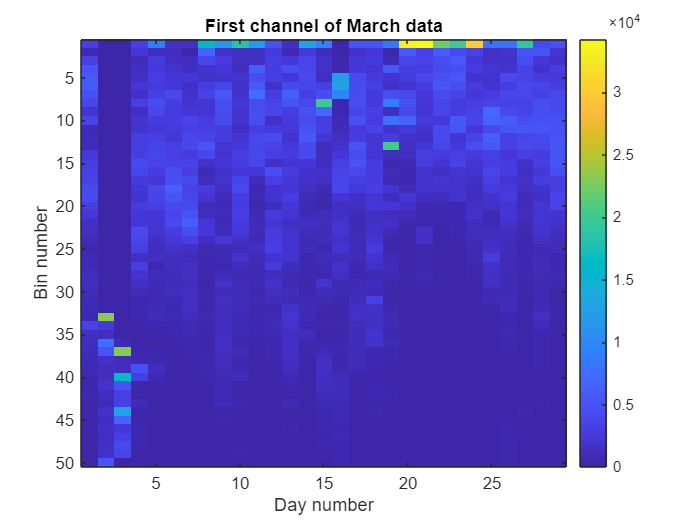

imagesc(histMatrix');
colorbar
ylabel('Bin number')
xlabel('Day number')
title('First channel of March data')